# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 15-Aug-2022 17:35:33

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([127 127 3],"Name","input")
    convolution2dLayer([11 11],96,"Name","Conv1_1","BiasLearnRateFactor",2,"Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","MaxPooling1_1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","Conv2 Grp_1","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([3 3],"Name","MaxPooling2_1","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","Conv3_1","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    groupedConvolution2dLayer([3 3],192,2,"Name","Conv4 Grp_1","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5 Grp_2","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([255 255 3],"Name","vinput")
    convolution2dLayer([11 11],96,"Name","Conv1","BiasLearnRateFactor",2,"Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu")
    maxPooling2dLayer([3 3],"Name","MaxPooling1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","Conv2 Grp","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([3 3],"Name","MaxPooling2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","Conv3","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    groupedConvolution2dLayer([3 3],192,2,"Name","Conv4 Grp","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5 Grp_1","BiasLearnRateFactor",2)
    batchNormalizationLayer("Name","batchnorm_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    helperMyCrossCorr("crossCorrilation",["in1" "in2"],"out")
    fullyConnectedLayer(6,"Name","fc12")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"batchnorm_9","crossCorrilation/in1");
lgraph = connectLayers(lgraph,"batchnorm_8","crossCorrilation/in2");

## Plot Layers

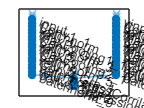

plot(lgraph);

function layer = helperMyCrossCorr(~,~,~)
layer = (MyCrossCorr('crossCorrilation'));
% Define this function before running the script.
% The function must create and return a layer of type MyCrossCorr.
end